# Domains Samples Using Standard Layers

Domains Standard Layers projects proceed in much the same way as a normal SL problem, except that there is an additional grouping step between layers an contrasts. 

Layers are grouped into 'Domain Contrasts'. The model for the actual experimental contrast is built from these domains rather than from layers. Thhere are exactly two domains for each contrast, with the the ratio of them controlled by a fittable 'domain ratio' parameter. 

            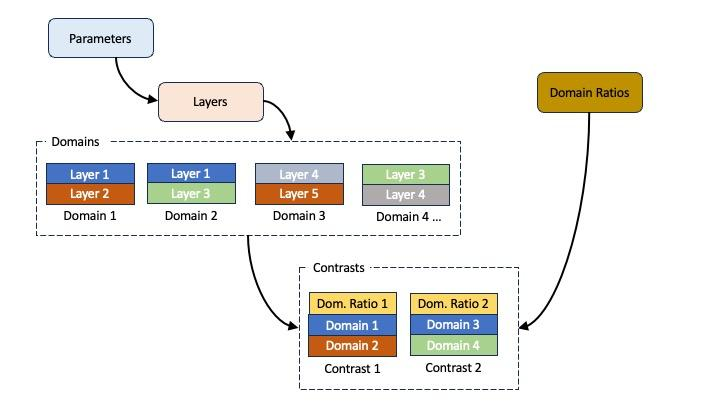

In this we will set up a simple example of a simulated system consisting of two layered domains to illustrate this process.

Start by making the project, specifying that this is a domains model...

problem = createProject(calcType="domains");

Define the parameters we need to define our two domains...

Parameters = {
    %   Name            min         val         max     fit?
    {'L1 thick',         5,         20,         60,     true   };
    {'L1 SLD',           3e-6,      4.1e-6,    5e-6,    false  };
    {'L1 rough'          2,          5,         20,     true   };
    {'L1 Hydr'           10,        20,         30,     true   };
    {'L2 thick',         5,         100,         60,    true   };
    {'L2 SLD',           3e-6,      2.1e-6,    5e-6,    false  };
    {'L2 rough'          2,          5,         20,     true   };
    {'L2 Hydr'           10,        20,         30,     true   };
    {'L3 thick',         5,         200,       300,     true   };
    {'L3 SLD',           3e-6,      7e-6,      8e-6,    false  };
    {'L3 rough'          2,          5,         20,     true   };
    {'L3 Hydr'           10,        20,         30,     true   };
    };

problem.addParameterGroup(Parameters);

..now group these into layers as usual....


Layer1 = {'Layer 1',...         % Name of the layer
    'L1 thick',...              % Layer thickness
    'L1 SLD',...                % Layer SLD
    'L1 Rough',...              % Layer roughness
    'L1 Hydr',...               % hydration (precent)
    'bulk out' }; 

Layer2 = {'Layer 2',...         % Name of the layer
    'L2 thick',...              % Layer thickness
    'L2 SLD',...                % Layer SLD
    'L2 Rough',...              % Layer roughness
    'L2 Hydr',...               % hydration (precent)
    'bulk out' }; 

Layer3 = {'Layer 3',...         % Name of the layer
    'L2 thick',...              % Layer thickness
    'L2 SLD',...                % Layer SLD
    'L2 Rough',...              % Layer roughness
    'L2 Hydr',...               % hydration (precent)
    'bulk out' };

problem.addLayerGroup({Layer1, Layer2, Layer3});


If we look at the project, there are two extra groups as compared to a normal standard layers - Domain Contrasts and Domain Ratios...

disp(problem)

         modelType: 'standard layers'
    experimentName: ''
          geometry: 'air/substrate'


    Parameters: ---------------------------------------------------------------------------------------------- 

    p             Name              Min      Value      Max     Fit? 
    __    _____________________    _____    _______    _____    _____

     1    "Substrate Roughness"        1          3        5    true 
     2    "L1 thick"                   5         20       60    true 
     3    "L1 SLD"                 3e-06    4.1e-06    5e-06    false
     4    "L1 rough"                   2          5       20    true 
     5    "L1 Hydr"                   10         20       30    true 
     6    "L2 thick"                   5        100       60    true 
     7    "L2 SLD"     

Now, make a couple of Domain Contrasts....


problem.addDomainContrast('Domain1');
problem.addDomainContrast('Domain2');


..and define which layers make up which domains...


problem.setDomainContrastModel(1,'Layer 1');
problem.setDomainContrastModel(2,{'Layer 2','Layer 3'});


Now make a contrast as with standard models, but this time also including the default domain ratio ("Domain Ratio 1)....

problem.addContrast('name','Domain Test',...
    'background',   'Background 1',...
    'resolution',   'Resolution 1',...
    'scalefactor',  'Scalefactor 1',...
    'resample',     false,...
    'BulkIn',       'SLD Air',...        
    'BulkOut',      'SLD D2O',...        
    'domainRatio',  'Domain Ratio 1',....
    'data',         'Simulation');

Dinally set the model for our contrast. Each physical contrast must have at least two domain contrasts and no more.....

problem.setContrastModel(1,{'Domain1','Domain2'});

Now we can run our simulation as usual, and plot the results....

% Make a controls class....
controls = controlsClass();

% Send everything to RAT....
[problem,results] = RAT(problem,controls);

Starting RAT ________________________________________________________________________________________________

Elapsed time is 0.022976 seconds.

Finished RAT ______________________________________________________________________________________________ 



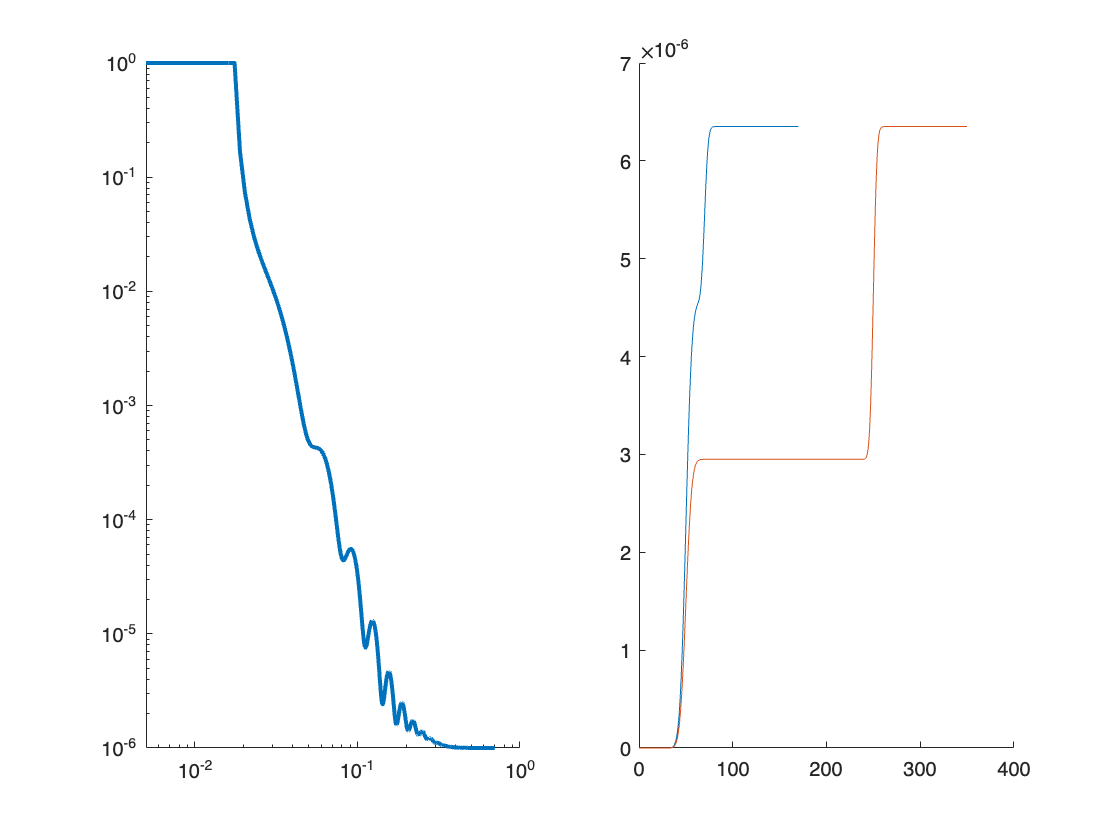


plotRefSLD(problem,results);